% csv_imageRead_demo_Hough_transform.mlx
%
% Last modified by George Bellesis, 7/5/2019
% 
% Read an image from a csv file, demonstrating how any type of 2D data
%   can be viewed as an image.
% 
% For the image Two_Lines.csv, finds two lines corresponding to
%   the two low and high regions in the image by using the
%   Hough Transform.
%   
%   Demonstrates how to hand tweak the Hough transform arguments to
%   deal with two closely spaced lines, where one is actually a broken line.
% 
% Compare to this Mathworks help file on the Hough transform:
%   FindLineSegmentsAndHighlightLongestSegmentExample.mlx
% 
% Next steps:
%   demonstrate fitting the data to a 3d line
%   generalize this demo for more images and a different number of features
% 
% Version 0.52, hard-coded to handle the image stored in one particular csv
%               file, 'Two_Lines.csv'


## Initialize

clear, close all


## Get image file

[filename,pathname]=uigetfile({'*.csv';'*.xlsx';'*.xls'},'Select a csv or SpreadSheet with Image Data');
cd(pathname)

tblMagnetoOpticImage = readtable(filename);
% tblMagnetoOpticImage = readtable('Two_Lines.csv');
tblProp=tblMagnetoOpticImage.Properties;
disp(['filename = ' filename])

filename = Two_Lines.csv


disp(tblProp)

  TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {1×1920 cell}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.



clear tblProp


## Convert to double and get statistics

doubleMagnetoOpticImage = table2array(tblMagnetoOpticImage);

imMin=min(min(doubleMagnetoOpticImage(:,:,1)));
imMax=max(max(doubleMagnetoOpticImage(:,:,1)));
imMedian=median(median(doubleMagnetoOpticImage(:,:,1)));

disp(['min median max: ' num2str(imMin) ' ' num2str(imMedian) ' ' num2str(imMax)])

min median max: 352 509.9789 708


## Display the image:

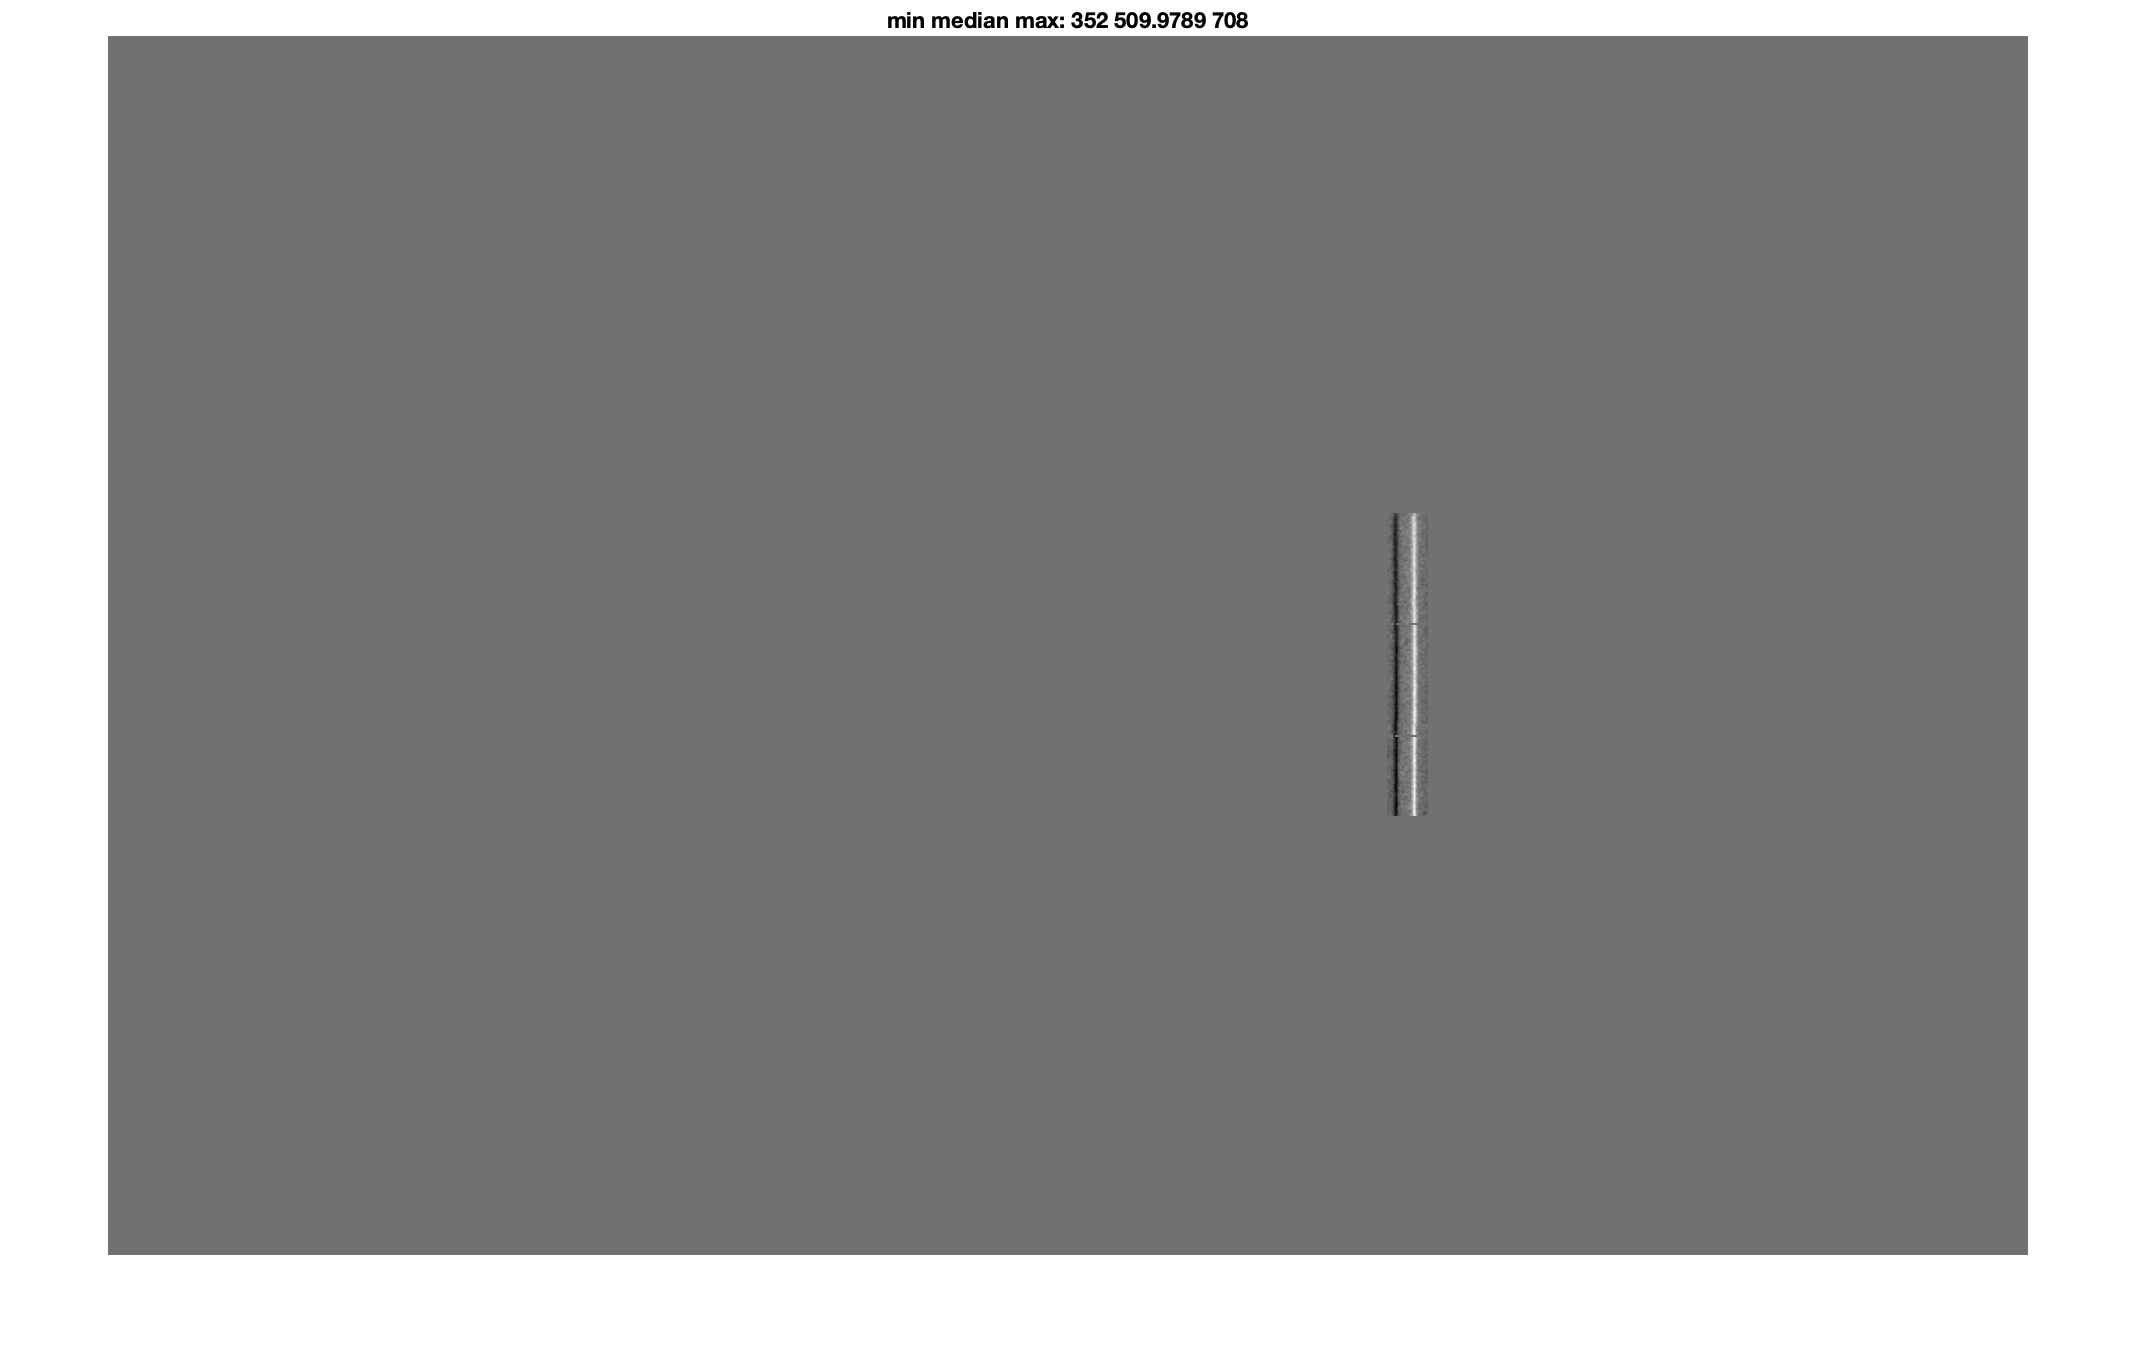

imshow(doubleMagnetoOpticImage,[imMin imMax])
title(['min median max: '... 
    num2str(imMin) ' ' num2str(imMedian) ' ' num2str(imMax)])

## Create a binary image

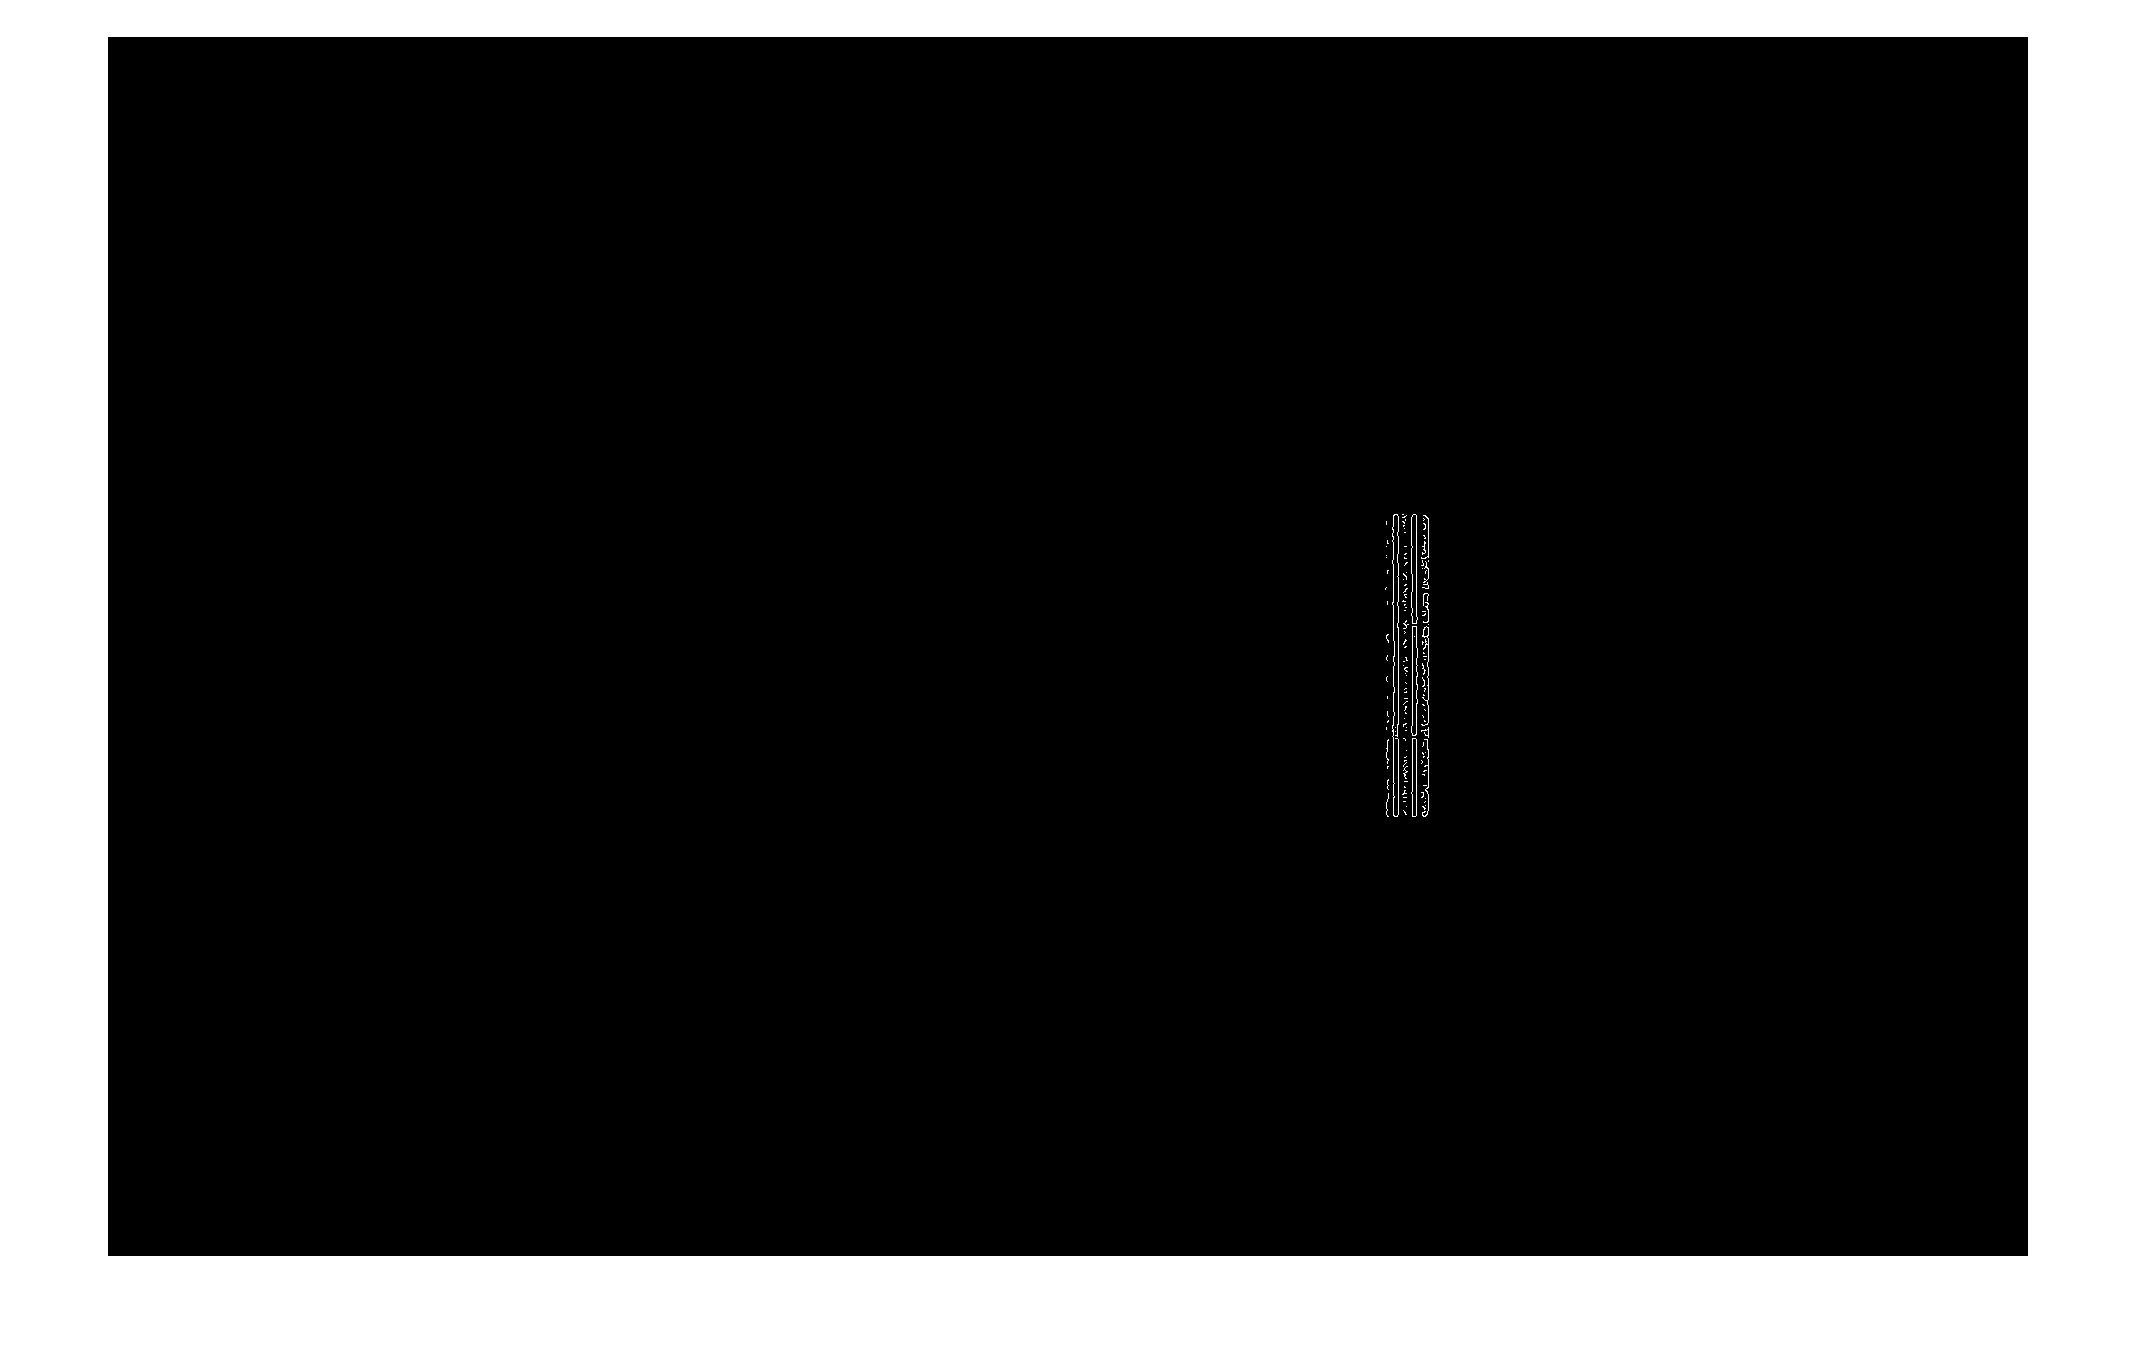

BW = edge(doubleMagnetoOpticImage,'canny');
imshow(BW)

## Create the Hough transform using the binary image

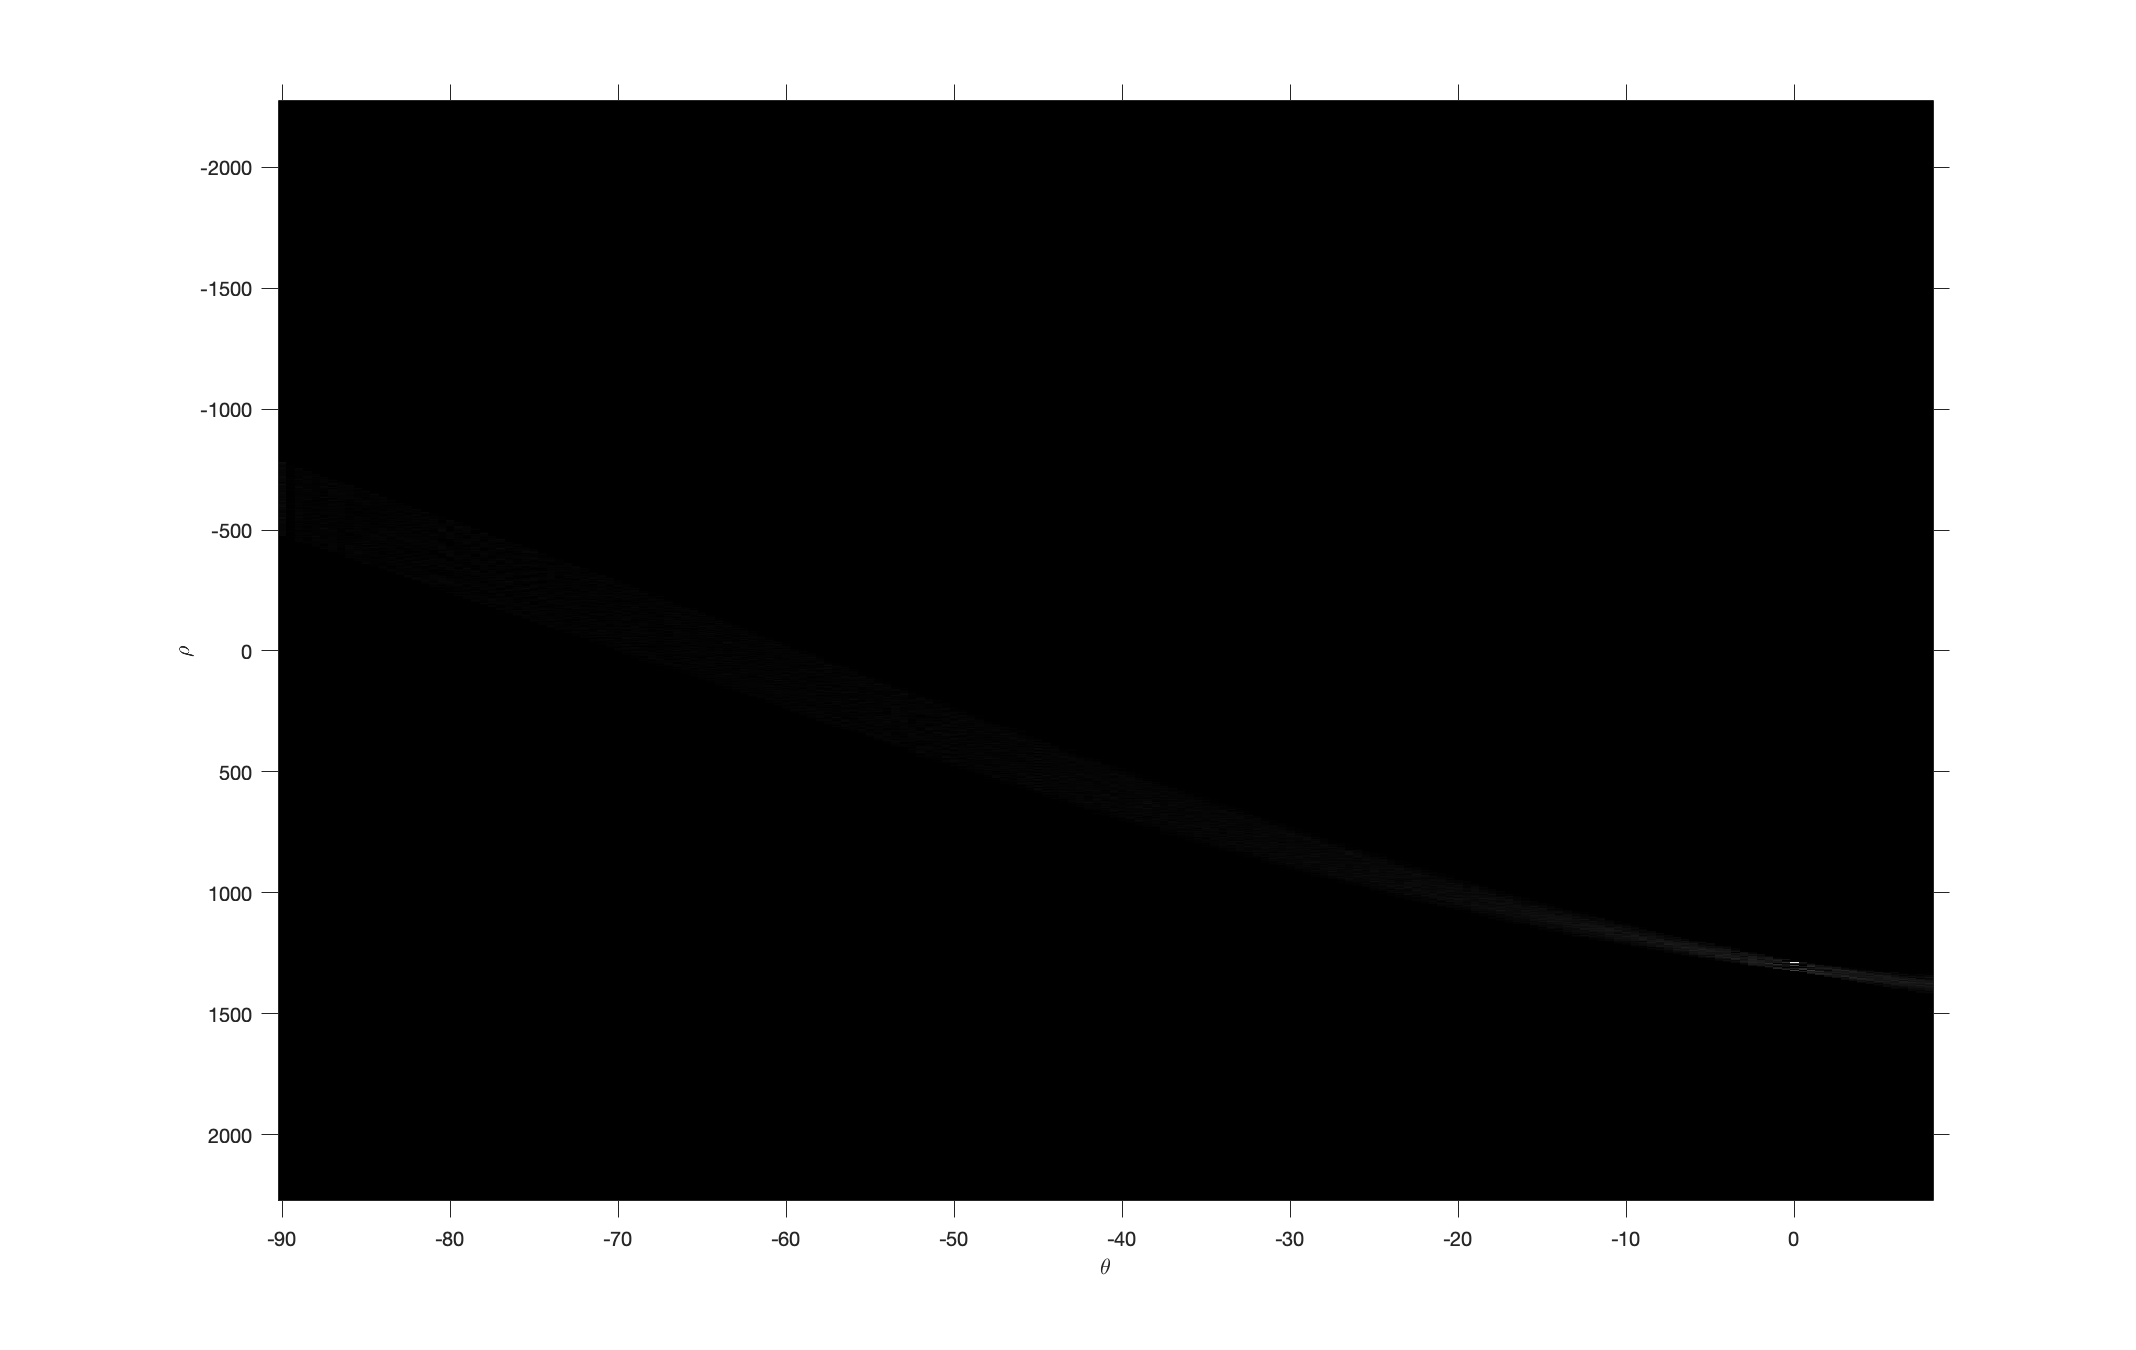

[H,T,R] = hough(BW,'RhoResolution',0.5,'Theta',-90:0.5:8);
imshow(H,[],'XData',T,'YData',R,...
            'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;

## Find peaks in the Hough transform of the image

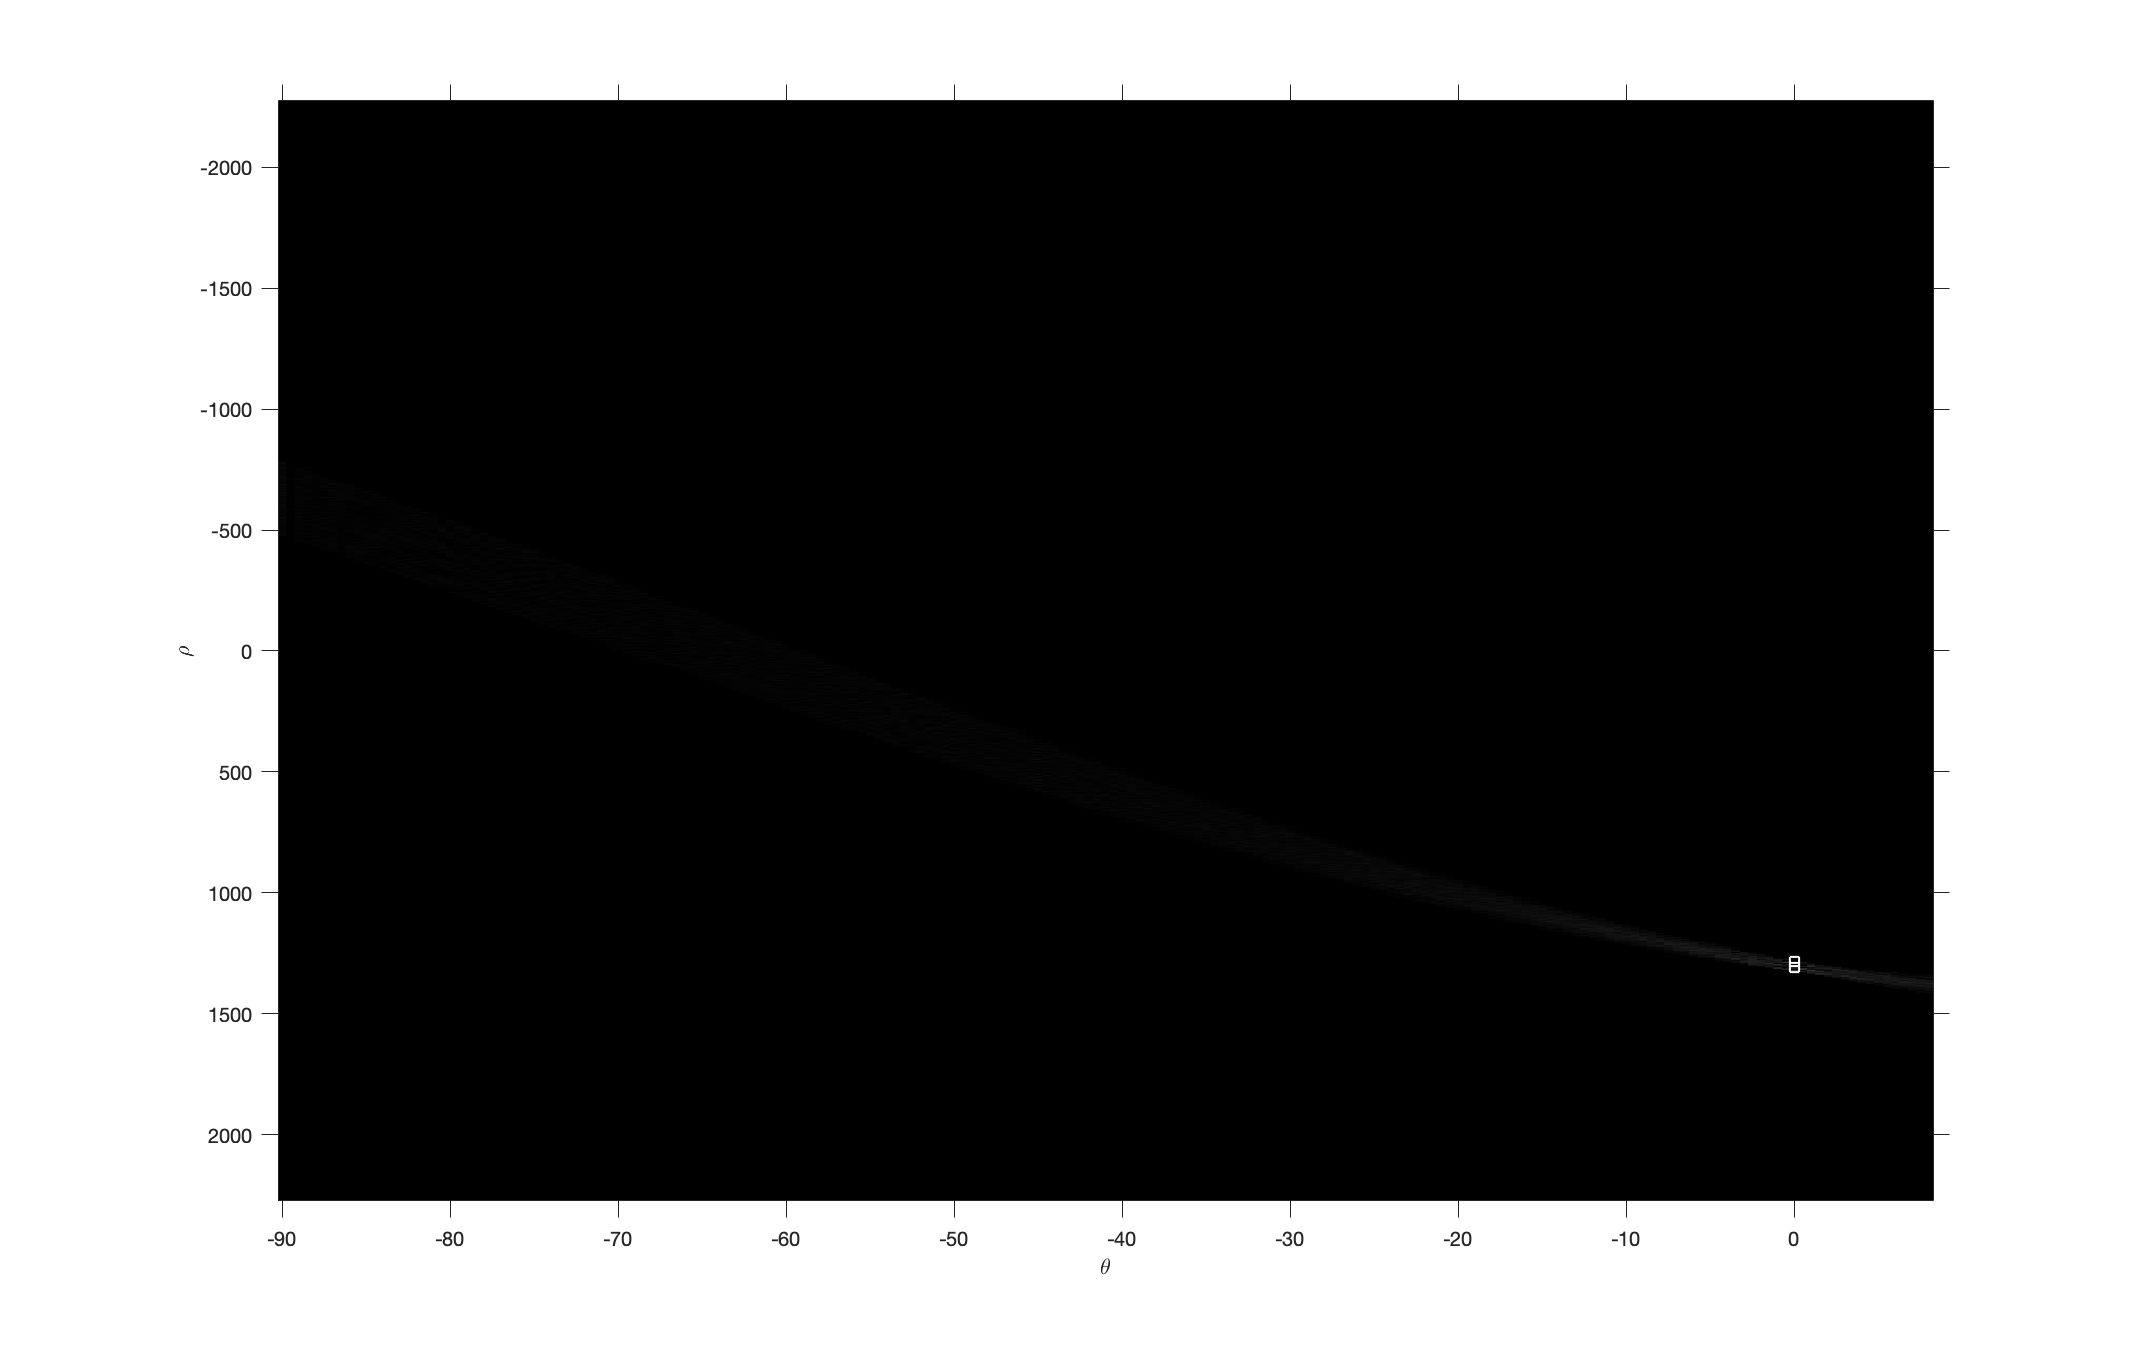

% P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
% The following was an attempt to match the default NHoodSize
% P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))),'NHoodSize',floor(size(H)/50));
% floor(size(H)/50) is [181 3]; choices must be odd; the following is set
% by hand to get the desired results, along with specifying two peaks:
P  = houghpeaks(H,2,'threshold',ceil(0.3*max(H(:))),'NHoodSize',[91 1]);
x = T(P(:,2)); y = R(P(:,1));
plot(x,y,'s','color','white');

## Find lines and plot them

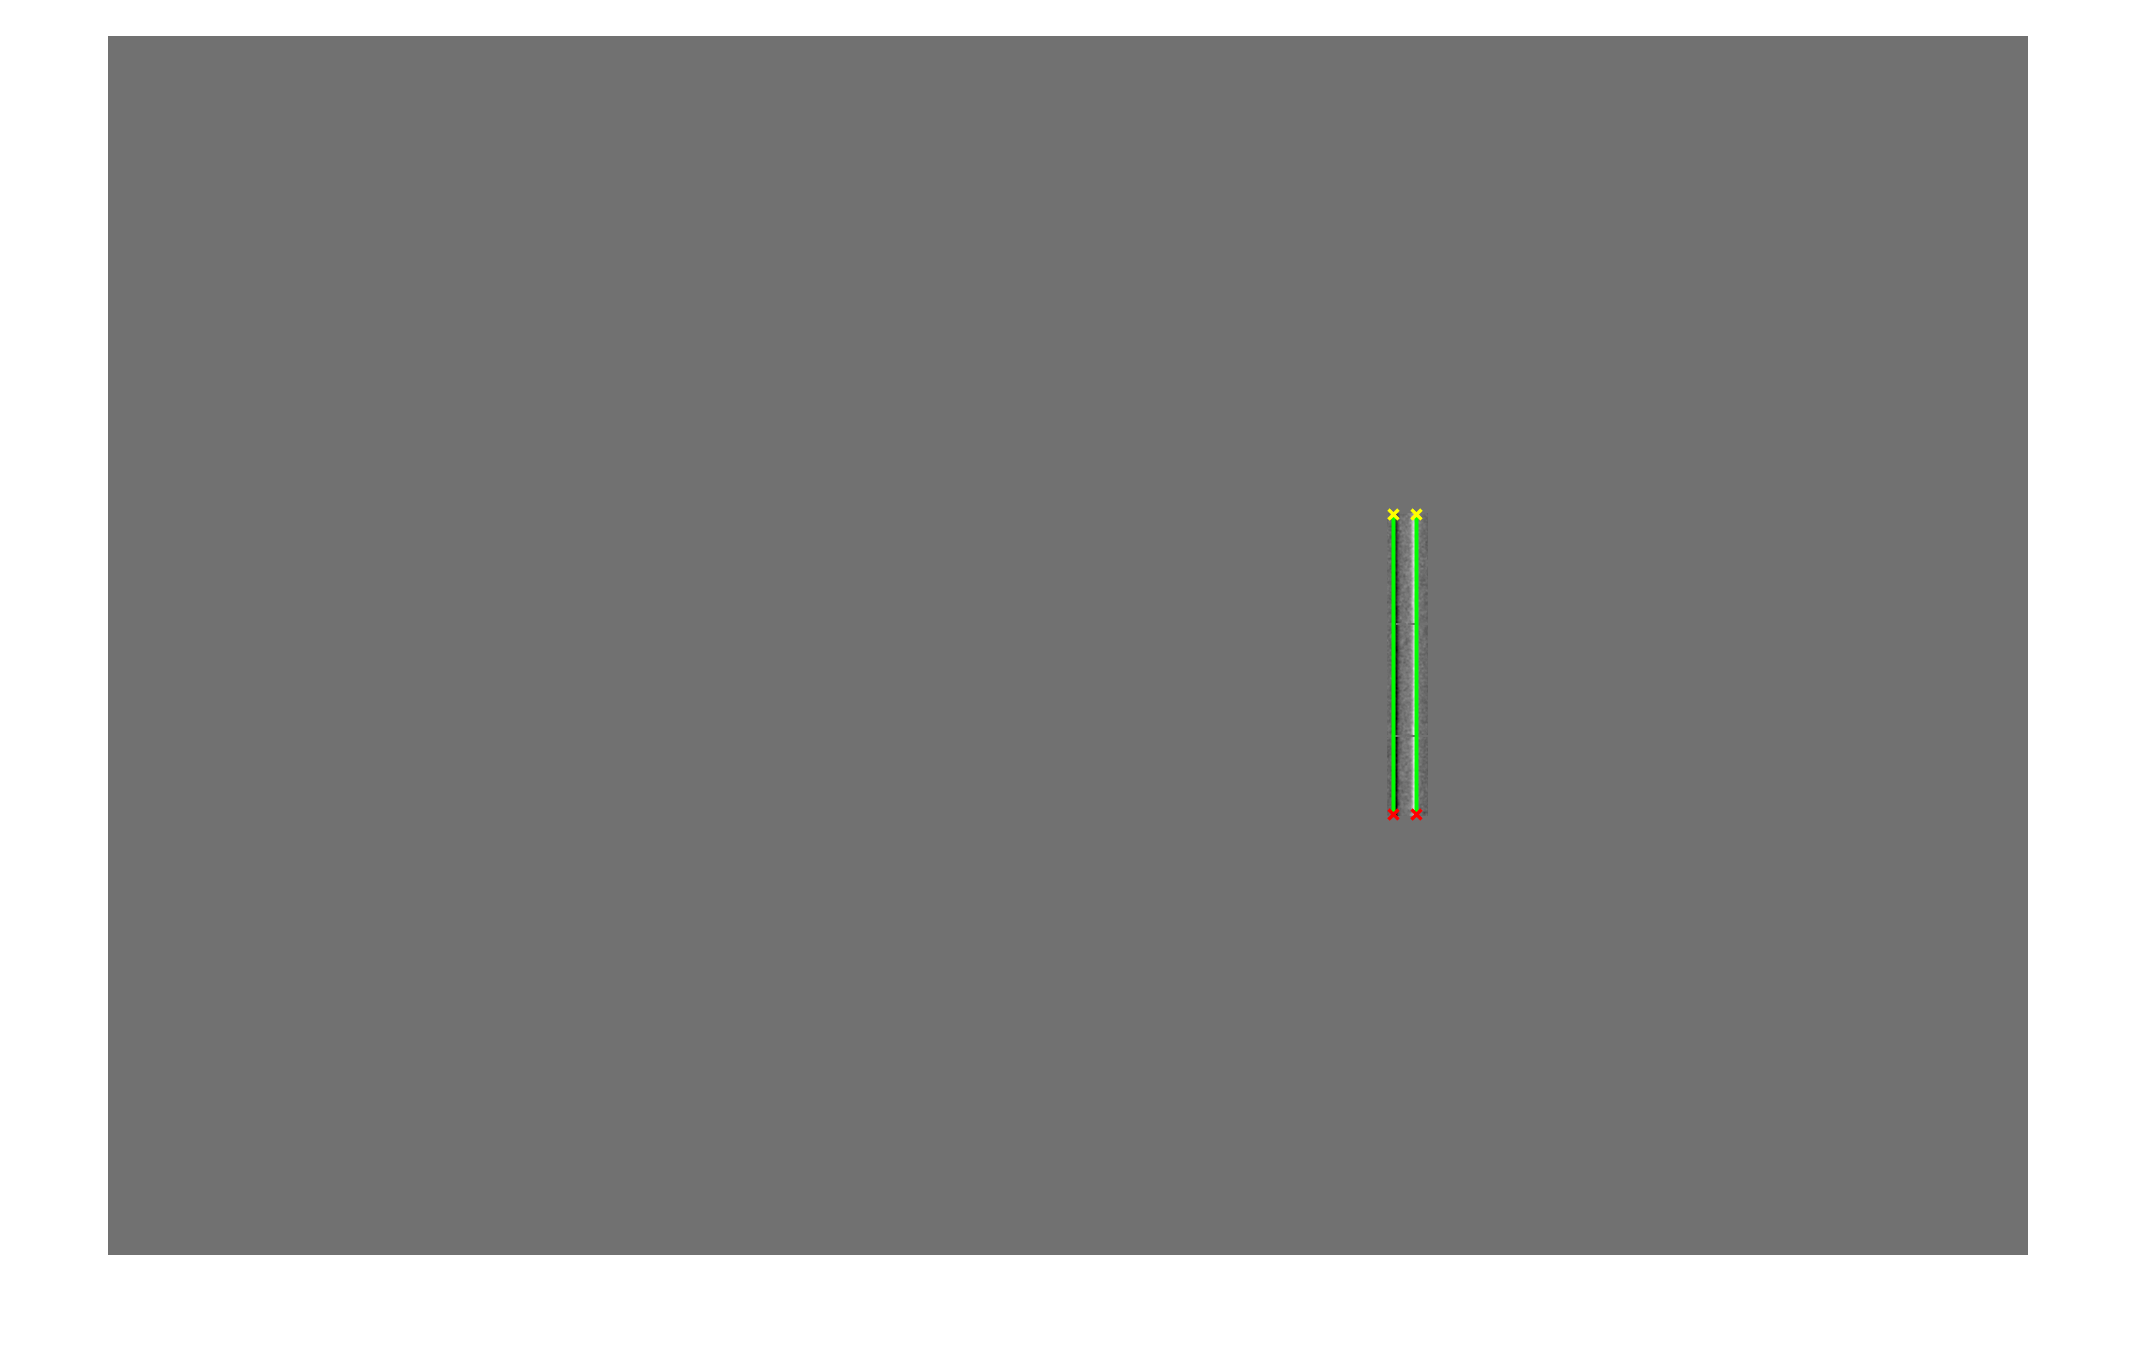

% A fillgap of 10 still results in two lines; 5 in three lines:
lines = houghlines(BW,T,R,P,'FillGap',20,'MinLength',7);
figure, imshow(doubleMagnetoOpticImage,[imMin imMax]), hold on
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end

## Highlight the longest line segment by coloring it cyan

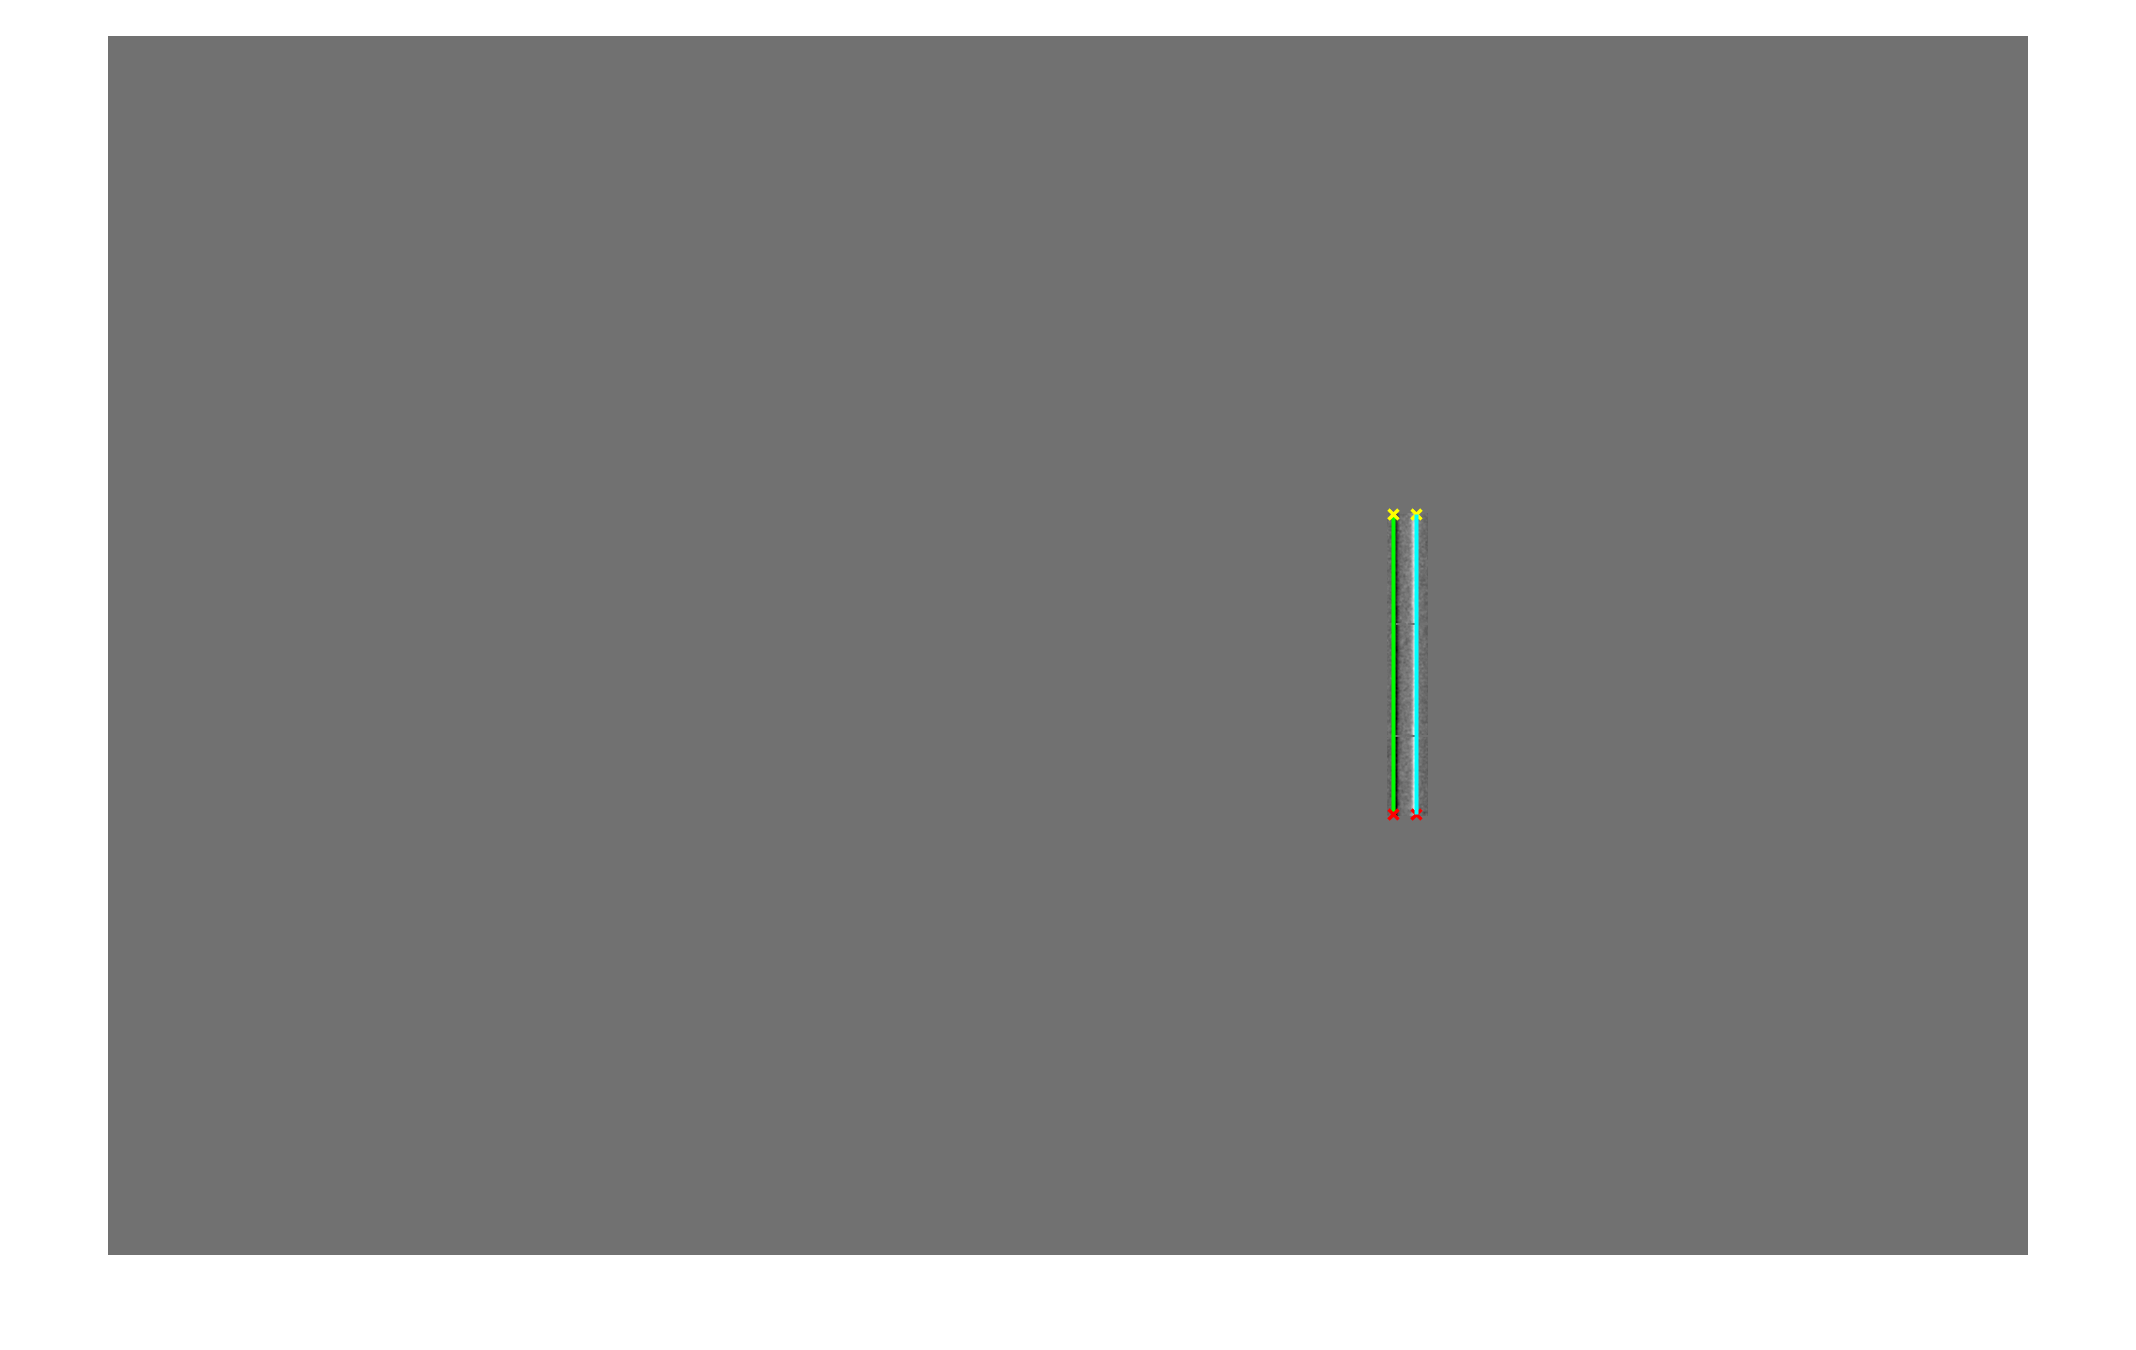

plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','cyan');
hold off

## Enlarge the region of interest

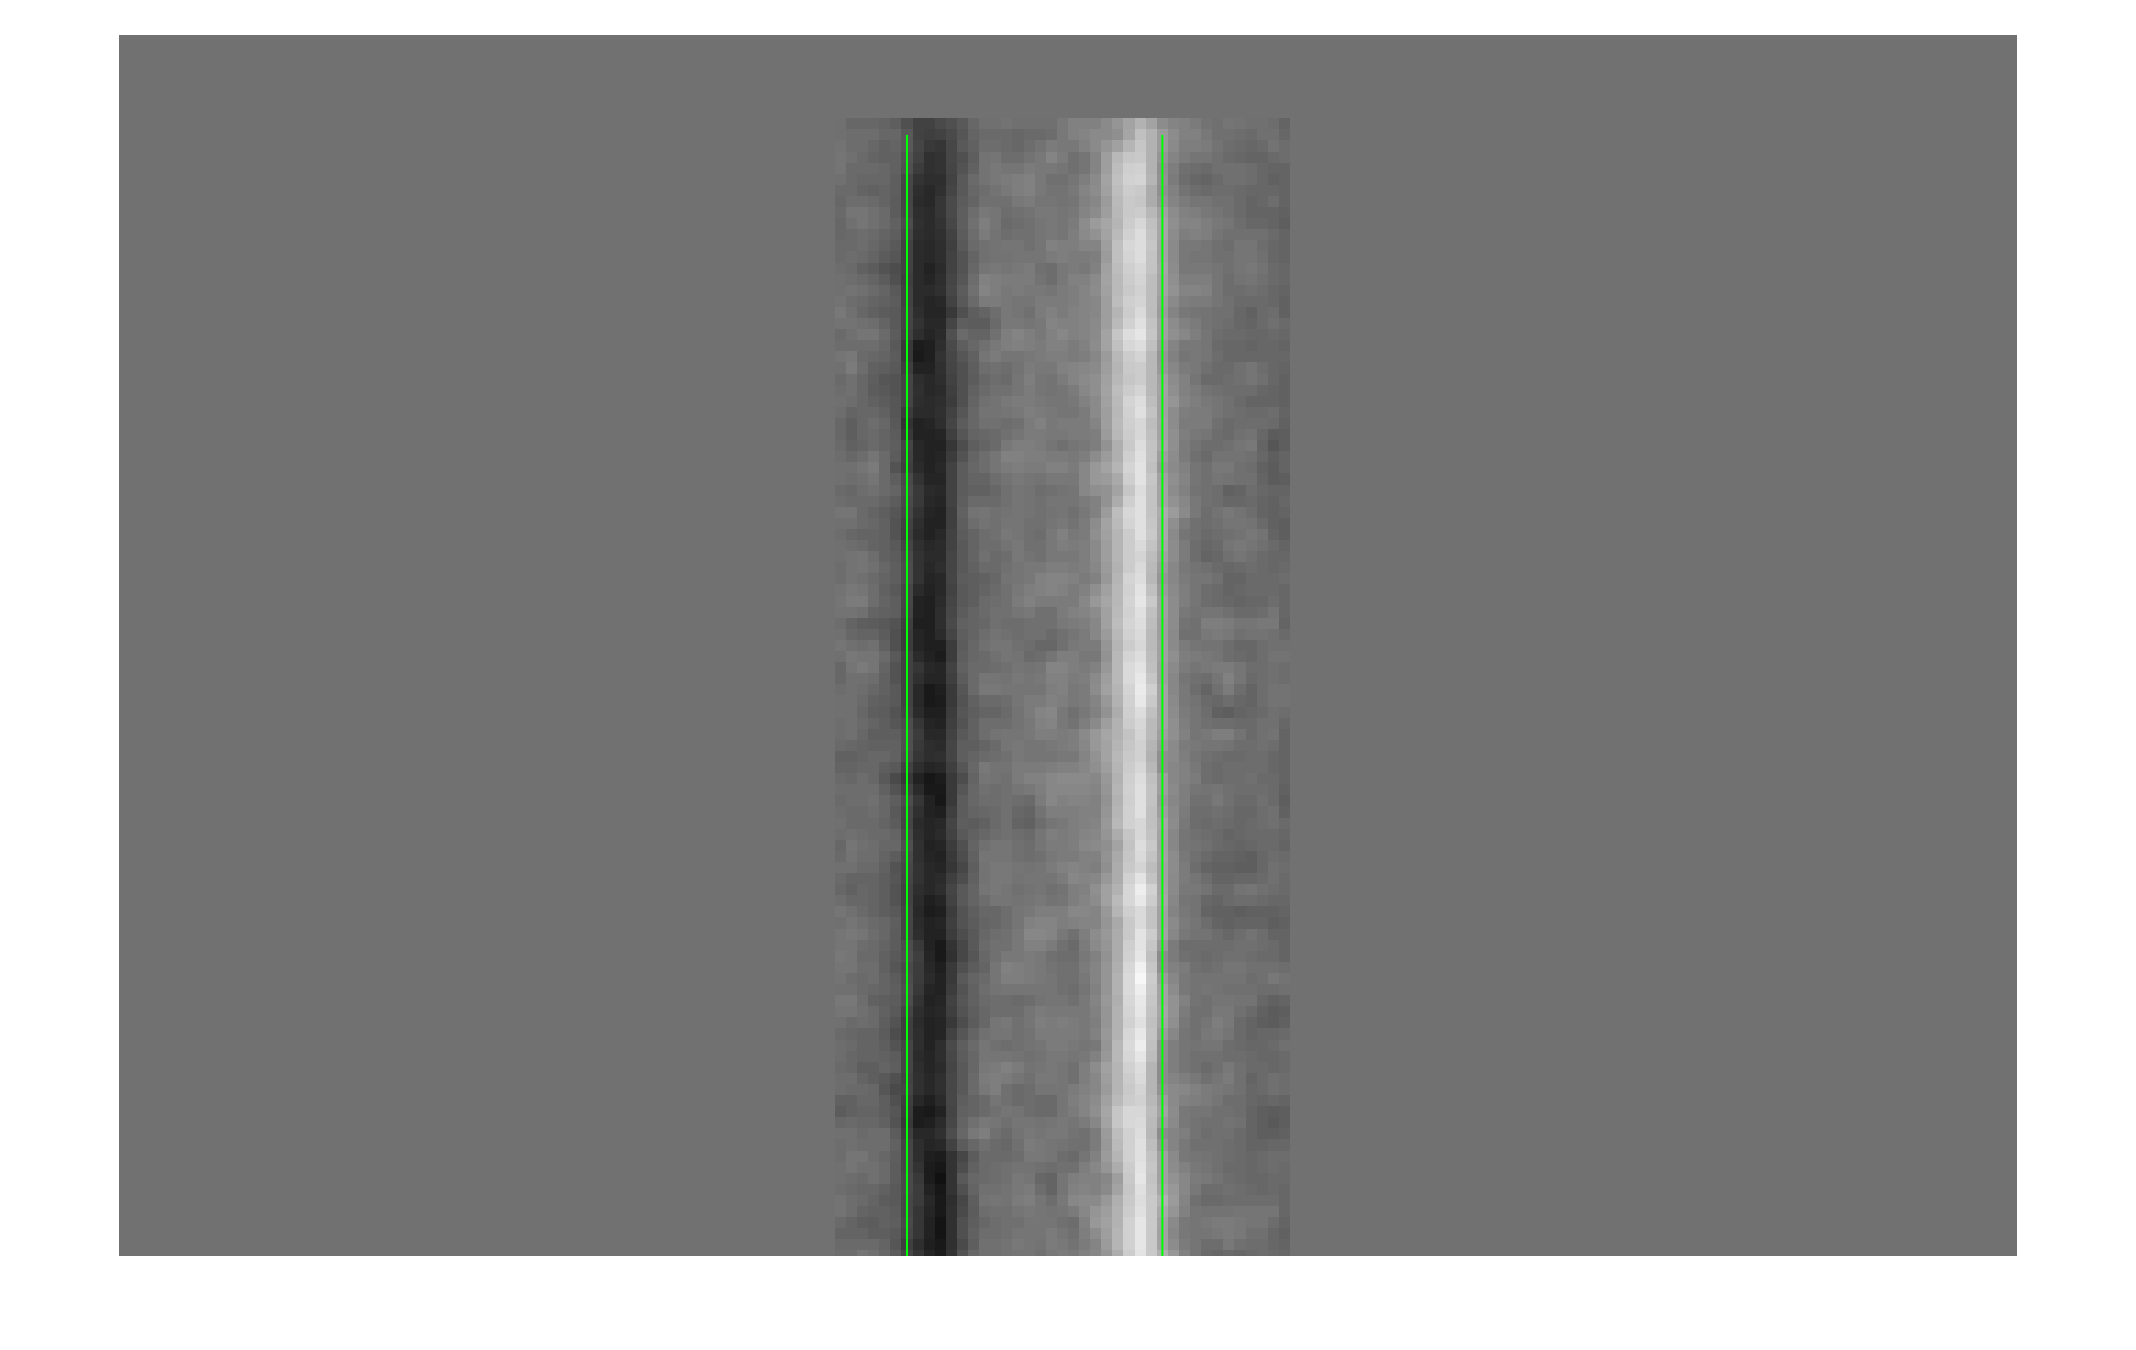

figure, imshow(doubleMagnetoOpticImage,[imMin imMax])
a = [1215 1386 470 580];
hold on
axis(a)
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',1,'Color','green');
end
hold off

## Find min and max between the two lines